## Problem 5

rng(0);

Generate a dataset comprising a set of $N$ real numbers drawn from the uniform distribution on $[0, 1]$. 

Consider various dataset sizes $N = 5, 10, 20, 40, 60, 80, 100, 500, 10^3 , 10^4$.

N=[5,10,20,40,60,80,100,500,10^3,10^4];  %sizes of datasets

For each $N$, repeat the following experiment $M := 100$ times: 

- first, generate the data, 

- then, compute the average $\hat{\mu}$, and 

- finally, measure the error between the computed average $\hat{\mu}$ and the true mean $\mu$ as $\left| \hat{\mu} - \mu_{true}\right|$.

M=100;
m_true=0.5;    % true mean of uniform distribution

exp_data_1=[];    % experimental data - 100x10 matrix -each column corrresponds to one value of N

for n=N
    mu_v = zeros(M,1);   % stores the difference between empirical and true averages for M iterations
    for i=(1:M)
        mu_v(i) = abs(mean(rand(n,1)) - m_true);   % difference between empirical and true average
    end
    exp_data_1 = [exp_data_1 mu_v];  % append this column to the already stored exp_data
end
disp(exp_data_1);

    0.1786    0.0399    0.2231    0.0119    0.0025    0.0351    0.0373    0.0094    0.0038    0.0004
    0.0691    0.0529    0.0439    0.0701    0.0205    0.0273    0.0570    0.0009    0.0176    0.0029
    0.1742    0.0619    0.0773    0.0054    0.0072    0.0026    0.0044    0.0109    0.0105    0.0013
    0.1462    0.0518    0.0641    0.0107    0.0192    0.0060    0.0080    0.0009    0.0013    0.0007
    0.1307    0.1122    0.0746    0.0113    0.0111    0.0030    0.0134    0.0136    0.0023    0.0047
    0.0440    0.0797    0.0386    0.0523    0.0116    0.0645    0.0427    0.0172    0.0011    0.0003
    0.2684    0.0854    0.0757    0.0070    0.0125    0.0346    0.0119    0.0006    0.0052    0.0010
    0.0640    0.1799    0.0067    0.0363    0.0362    0.0425    0.0133    0.0185    0.0041    0.0000
    0.0136    0.0431    0.0104    0.0184    0.0041    0.0372    0.0093    0.0034    0.0037    0.0001
    0.1091    0.2067    0.0288    0.0168    0.0192    0.0177    0.0010    0.0027    0.0229 

- For the uniform distribution, plot a single graph that shows the distribution of errors (across $M$ repeats) for all values of $N$ using a box-and-whisker plot. You may use the boxplot(.) function in Matlab. 

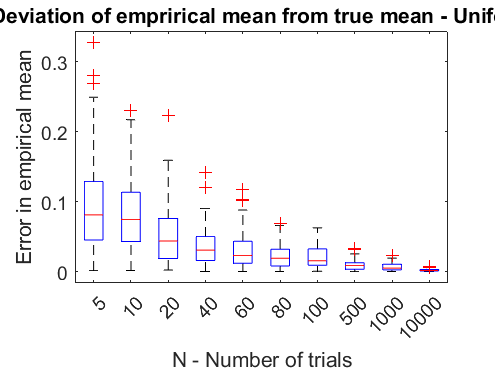

boxplot(exp_data_1,N), xlabel("N - Number of trials"), ylabel("Error in empirical mean"), title("Deviation of emprirical mean from true mean - Uniform");

-  Repeat the above question by replacing the uniform distribution by a Gaussian distribution with $\mu := 0$ and $\sigma^2 := 1$. 

mu=0;     %true mean is 0
sigma=1;   %standard deviation parameter
exp_data_2=[];  % experimental data - 100x10 matrix -each column corrresponds to one value of N

for n=N
    mu_v = zeros(100,1); % stores the difference between empirical and true averages for M iterations
    for i= 1:100
        mu_v(i) = abs(mean(random('Normal',mu,sigma,n,1)) - mu);  % difference between empirical and true average
    end
    exp_data_2 = [exp_data_2 mu_v];  % append this column to the already stored exp_data
end
disp(exp_data_2);

    0.0170    0.6528    0.0614    0.0861    0.0569    0.0262    0.0912    0.0734    0.0064    0.0104
    0.2548    0.6650    0.3918    0.1096    0.1201    0.0368    0.1050    0.0209    0.0317    0.0198
    0.1035    0.3671    0.1756    0.1445    0.1010    0.1539    0.1392    0.0296    0.0024    0.0144
    0.2999    0.0876    0.1185    0.0060    0.2013    0.0792    0.1247    0.0292    0.0014    0.0026
    0.1405    0.3150    0.3369    0.3275    0.0682    0.1597    0.0863    0.0385    0.0380    0.0073
    0.1654    0.7752    0.2552    0.1121    0.1754    0.2019    0.0869    0.0076    0.0463    0.0064
    0.2098    0.2140    0.0328    0.0161    0.0045    0.0330    0.1320    0.0588    0.0528    0.0069
    0.0136    0.2282    0.2096    0.0519    0.1877    0.0378    0.1058    0.0880    0.0226    0.0056
    0.2370    0.1456    0.3731    0.2333    0.0776    0.0743    0.0371    0.0018    0.0184    0.0143
    0.4823    0.0578    0.4278    0.0735    0.3727    0.2593    0.2060    0.0450    0.0236 

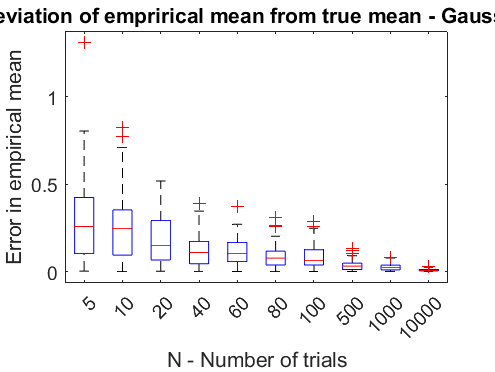


boxplot(exp_data_2,N), xlabel("N - Number of trials"), ylabel("Error in empirical mean"), title("Deviation of emprirical mean from true mean - Gaussian");;

-  Interpret what you see in the graphs. What happens to the distribution of error as $N$ increases ? 

When the value of N is small, the data that is generated is more random than the data generated when N is large. So for small N, the spread in the deviations from the true mean are relatively high. As N increases to large enough values(say 1000 and 10000), the mean values obtained over the M(100) iterations are almost equal to the true mean value. In fact, there is barely any data set that is conspicuously farther from 0 when N = 10000; as is evident from the graph.

In conclusion, the distribution of error decreases as N increases.